% House Keeping
clear;
clc;

#### Errikos Flight Regime Sample

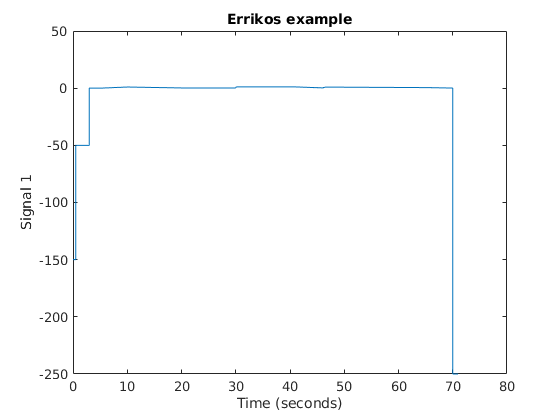

errikos_test = load("./Simulink Testing/samplemission.mat");
errikos_test = errikos_test.Scenario{1};

plot(errikos_test);
title("Errikos example");

#### Variables for Generating Flight Regimes

flightLen_max = 300;        % 5 mins
flightLen_min = 60;         % 1 min

sampleT = 0.05;             % from the Testing_Model simulink
samplingFreq = 1/0.05; 

numberOfTests = 1000;       % number of flight regimes we will generate and test

#### Generating Flight Regimes

flightReg_finalT = randi([flightLen_min, flightLen_max], 1, numberOfTests); % generating durations for the flight regimes
performance_array = zeros(1,numberOfTests);                                 % initializing performance array

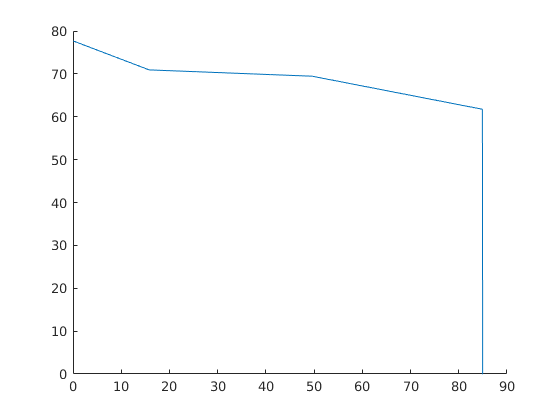

% This block of code could be made more efficient

figure()
hold on

% Iterate over the generated flight regimes
% for i = 1:numberOfTests
for i = 1:1
    
    % Getting all the t_i for the current flight test
    flightReg_time = [0:sampleT:flightReg_finalT(i)];
    
    % Selecting number of sections we will divide each test into
    %num_sections = round(0.05 * flightReg_finalT(i) ); % this will be it
    
    num_sections = 3;   % for testing
    r = rand(1, 3);     % for testing
    
    % "r" holds the duration of each section
    %r = rand(1, num_sections)*.1;      % generating r
    r = r / sum(r);                     % sum of r = 1
    r = r .* flightReg_finalT(i);       % sum of r = flight test time
   
    % Duration of each section is rounded to the closest sampleT
    for j = 1:length(r)
        r(j) = round(r(j)/sampleT)*sampleT;
    end
    
    % For Debugging
    %fprintf("Duration of flight test: %d seconds", flightReg_finalT(i));
    
    % Variables
    starting_t  = 0.00; % so that the "section_output" works
    starting_idx = 1;   % for adding the "section_output" to "Desired Height"
    last_x = 0;         % this will be used to ensure continuity
    last_y = 0;         % this will be used to ensure continuity
    
    % Initiating array of "Desired Heights"
    flightReg_DesiredHeight = zeros(1,length(flightReg_time));
    
    % Populating array of "Desired Heights"
    for m = 1:length(r)
       
        section_duration = r(m); % just for readability
        
        % For debugging
        %fprintf("m = %d; starting time %.2f; section duration %.2f\n", m, starting_t, section_duration);
        
        % Variables that "selects" the signal type of each section
        selectSignalType = rand();
        
        % Otherwise code below breaks (there is prob a better way)
        if starting_t ~= 0
             last_x = flightReg_time(starting_idx -1);
             last_y = flightReg_DesiredHeight(starting_idx -1);
        end
        
        % Sin Signal
        if (selectSignalType < 0)
            
            % Getting random coefficients and Sin Output
            [a,b,c,f] = new_sine_coef();
            section_output = discSin([0.0:sampleT:section_duration], a, b, c, f);
            
            % Debugging
            %fprintf("SINE: a=%.2f, b=%.2f, c=%.2f, f=%.2f", a, b, c, f); 
            
        % Linear Signal
        elseif (selectSignalType < 1)
            
            % Getting random coefficients and Linear Output
            [m, b] = new_line_coef(last_x, last_y);
            section_output = discLin([starting_t:sampleT:starting_t+section_duration], m, b);
            
            % Debugging
            %fprintf("Size output: %f", size(section_output));
            %fprintf("LINE: m=%.2f, b=%.2f", m, b);
            %fprintf("Starting idx: %f", starting_idx);
            %fprintf("FInal idx: %f", final_idx);
            
        % Exp Signal
        else
            
            % Getting random coefficients and Exp Output
            [a,b,c] = new_exp_coef(last_x, last_y);
            section_output = discExp([starting_t:sampleT:starting_t+section_duration], a, b, c);
                        
            % Debugging
            %fprintf("EXP: a=%.2f, b=%.2f, c=%.2f", a, b, c);
            
            
        end
         
        final_idx = starting_idx + round(section_duration/sampleT);     % getting index of final time
        
        % Adding "section_output" to "flightReg_DesiredHeight" 
        % (prob can also be improved)
        for (k = starting_idx:final_idx-2)
            flightReg_DesiredHeight(k) = flightReg_DesiredHeight(k) + section_output(k-starting_idx + 1);
        end
        flightReg_DesiredHeight(final_idx-1) = flightReg_DesiredHeight(final_idx-1) + section_output(final_idx-starting_idx);
        
        
        starting_t = starting_t + section_duration;         % updating starting time
        starting_idx = final_idx;                           % updating starting index
    end
    
    %{
    % Get the real height using the controller
    realHeight_array = function(...)
    
    % Getting MSE of our tracking in this flight regime
    iteration_meanSquareError = getPerformance(flightReg_DesiredHeight, realHeight_array)
    
    performance_array(i) = iteration_meanSquareError;
    %}
    
    
    % For Debugging!
    % Plotting Generated Flight Regime
    plot(flightReg_time, flightReg_DesiredHeight);

end
% Get overall performance for this controller 
% (i.e. mean of "performance_array", variance, ...)

hold off

%{
OLD METHODOLOGIES - NOT RELEVANT

                % OLD IDEA
    % num_sections = round(flightReg_finalT(i)/3); % divide "flight test" into sections of 3 seconds
    

            % Adding result to flightReg_DesiredHeight
            %temp2=1;
            %for (k = find(flightReg_time==starting_t):find( abs(flightReg_time - end_t)<1e-3 )-1)
            %    %disp(k)
            %    flightReg_DesiredHeight(k) = flightReg_DesiredHeight(k) + section_output(temp2);
            %    temp2 = temp2 + 1;
            %end
%}

#### # Debugging purposes only!

The comments are just what i though was reasonable values for the flight regime! They should be debated/considered!

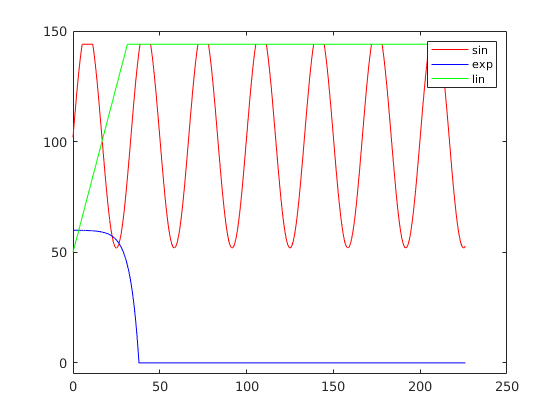

figure()

a = 50;     % amplitude between         [5, 40] cm
b = 102;    % oscillation mean between  [0, 144] cm
c = 0;      % phase shift between       [0, 2*pi] rad
f = 0.03;   % frequency between         [0.03, 0.15] 
output = discSin(flightReg_time, a, b, c, f);
plot(flightReg_time, output, "r")

hold on

%MIGHT NEED TO FIX THE RANGE OF A AND C FOR THE EXPONENT, NOT SURE IM CURRENTLY GETTING THE FULL RANGE (i.e. e^-x)%

a = -.03;     % ----                     [-0.5, 0.5]
b = 60;     % y intercept between       [0, 144] cm
c = 0.2;    % ----                      [0.2, 0.5]
output = discExp(flightReg_time, a, b, c);
plot(flightReg_time, output, "b")

m = 3;     % slope between             [-70, 70] (note that large slopes simulate step changes)
b = 50;     % y intercept between       [0, 144] cm
output = discLin(flightReg_time, m, b);
plot(flightReg_time, output, "g")

% introduce step change!! function (i.e. linear with different ranges of m)
% [-70, 70] (note that large m slopes simulate step changes)

legend("sin", "exp", "lin")
ylim([-5,150]);  % to check that the capping is working
hold off

### Signal Generation Functions

#### Capping possible values

function [capped_array] = capArray(capped_array)
    capped_array(capped_array>144) = 144;
    capped_array(capped_array<0) = 0;
end

#### Sine: $y = A\cdot \sin(2\pi \cdot f\cdot t+c) + b$

function [output_array] = discSin(time_array, a, b, c, f)
    output_array = a .* sin(2 .* pi .* time_array .* f + c) + b;
    output_array = capArray(output_array);
end

#### Exp: $y = A\cdot \exp(c \cdot t) + b$

function [output_array] = discExp(time_array, a, b, c)
    output_array = a .* exp(c .* time_array) + b;
    output_array = capArray(output_array);
end

#### Exp: $y = m\cdot x+b
$

function [output_array] = discLin(time_array, m, b)
    output_array = (time_array .* m) + b;
    output_array = capArray(output_array);
end

#### Coefficient Generator Functions

function [a,b,c,f] = new_sine_coef()
    % Generating random sine coefficients
    a = 35 * rand() + 5;
    b = 144 * rand();
    c = 2*pi * rand();
    f = 0.12 * rand() + 0.03;
end

function [m, b] = new_line_coef(last_x, last_y)
    % Generating random linear coefficients
    m = 2 * rand() - 1;
    
    if last_x ~= 0
        b = last_y - (last_x * m);
    else
        b = 144 * rand();
    end
    
end

function [a, b, c] = new_exp_coef(last_x, last_y)
    % Generating random exponential coefficients
    a = rand() - 0.5;
    c = 0.3 * rand() + 0.2;
    
    % If this is the 1st section, no need for ensuring continuity with the
    % previous one
    if last_x ~= 0
        b = last_y - a * exp(c*last_x);
    else
        b = 144 * rand();
    end
end

### Performance Functions

function [track_error] = getPerformance(desiredH_arr, realH_arr)
    track_error = mean( (desiredH_arr - realH_arr).^2 );        % Mean square-error
end